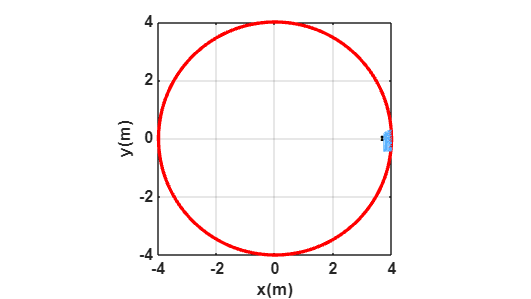

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%% TRAYECTORIA COMPLETA %%%%%%%%%%%%%%%%%%%%%%%%%%%

r = 4;  % Radio
theta = linspace(0, 2*pi, 300);  % Ángulo de 0 a 2pi (círculo completo)

hx_square = r * cos(theta);  % x(t) desplazado para que entre en escena [0 a 8]
hy_square = r * sin(theta);  % y(t) desplazado para que entre en escena [0 a 8]

%%%%%%%%%%%%%%%%%%%%%% ORIENTACIÓN DEL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

phi_square = atan2(diff(hy_square), diff(hx_square));
phi_square(end+1) = phi_square(end);  % Igualar longitudes

x1_square = hx_square;  % Para animación con robot
y1_square = hy_square;

N_square = length(theta);
ts = 0.03;  % Tiempo de muestreo

%%%%%%%%%%%%%%%%%%%%%%%% SIMULACIÓN GRÁFICA %%%%%%%%%%%%%%%%%%%%%%%
scene1 = figure;
set(scene1,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene1,'position',sizeScreen);
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([2]);
axis([-4 4 -4 4 0 2]);

scale = 4;  % Tamaño del robot
MobileRobot_5; % Cargar modelo del robot
H1 = MobilePlot_4(x1_square(1), y1_square(1), phi_square(1), scale); hold on;
H2 = plot3(hx_square(1), hy_square(1), 0, 'r', 'lineWidth', 2);

% Animación del movimiento
for k = 1:N_square
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1_square(k), y1_square(k), phi_square(k), scale);
    H2 = plot3(hx_square(1:k), hy_square(1:k), zeros(1,k), 'r', 'lineWidth', 2);
    pause(ts);
end